L0=6.15;  
L1=1.00;
L2=7.05;
L3=1.35;
L4=7.55;
L5=0.85;

L_PC(1) = Link('revolute','alpha', 0,    'a', 0,    'd',L0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L_PC(2) = Link('revolute','alpha', pi/2, 'a', L1,   'd',0,   'offset', pi/2,   'modified', 'qlim',[deg2rad(-110) deg2rad(110)]);
L_PC(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[deg2rad(-60) deg2rad(65)]);
L_PC(4) = Link('revolute','alpha', pi/2, 'a', L3,   'd',L4,   'offset', pi,   'modified', 'qlim',[deg2rad(-200) deg2rad(200)]);
L_PC(5) = Link('revolute','alpha', -pi/2,'a', 0,    'd',0,   'offset', pi,   'modified', 'qlim',[deg2rad(-120) deg2rad(120)]);
L_PC(6) = Link('revolute','alpha', pi/2, 'a', 0,    'd',L5,   'offset', 0,   'modified', 'qlim',[deg2rad(-400) deg2rad(400)]);
R6_PC = SerialLink(L_PC,'name','Robot_{RRRRRR}')

 
R6_PC = 
 
Robot_{RRRRRR} (6 axis, RRRRRR, modDH, fastRNE)                  
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|       6.15|          0|          0|          0|
|  2|         q2|          0|          1|      1.571|      1.571|
|  3|         q3|          0|       7.05|          0|          0|
|  4|         q4|       7.55|       1.35|      1.571|      3.142|
|  5|         q5|          0|          0|     -1.571|      3.142|
|  6|         q6|       0.85|          0|      1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0            

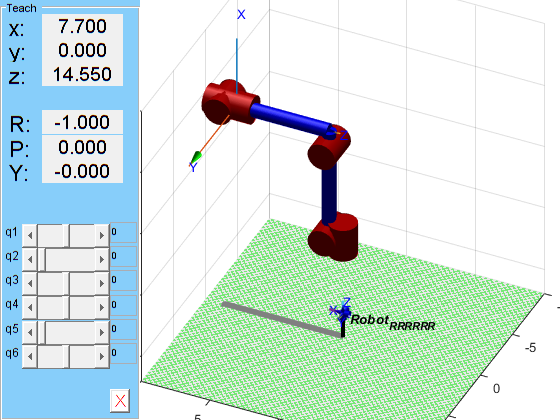


R6_PC.plot([0 0 0 0 0 0],'workspace',[-10 10 -10 10 -2 20],'xyz', 'view',[30 30]);
hold on
trplot(eye(4), 'width',2,'arrow')
R6_PC.teach()
hold off

view([-155.1 36.2])